# Tic Detection

## Load Datasets and Trials for Computation

% Define the Trials Number and Folder
clear; clc; close all;
Folder = 'C:\Users\jcagle\Documents\Brain Mapping Laboratory\TS03\2016_11_07';
Trial = 01;

% Load Datas
cd(Folder);
Experiments = fullPath(Folder,'Processed*.mat');
Data = load(Experiments{Trial});

## Display the Data

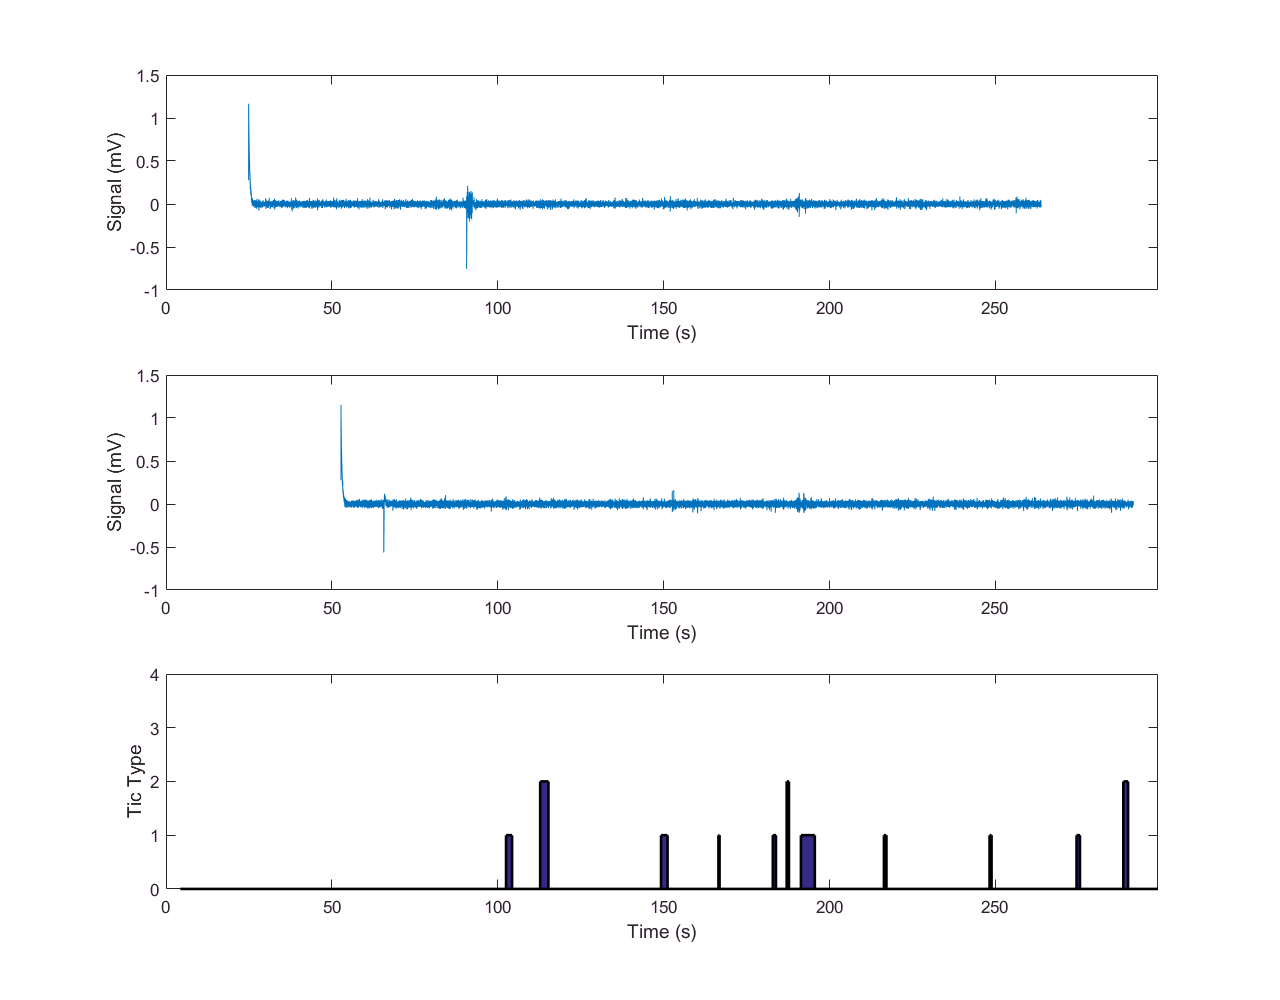

largeFigure(1800, [1280 1000]); clf;
subplot(3,1,1);
plot(Data.Left_DBS.TimeRange - Data.DBS_Bias(1), Data.Left_DBS.data(:,3),'linewidth',0.1);
xlabel('Time (s)','fontsize',15);
ylabel('Signal (mV)','fontsize',15);
set(gca,'fontsize',13);
xlim([0 max(Data.Marker.time - Data.EMG_Bias)]);

subplot(3,1,2);
plot(Data.Right_DBS.TimeRange - Data.DBS_Bias(2), Data.Right_DBS.data(:,3),'linewidth',0.1);
xlabel('Time (s)','fontsize',15);
ylabel('Signal (mV)','fontsize',15);
set(gca,'fontsize',13);
xlim([0 max(Data.Marker.time - Data.EMG_Bias)]);

subplot(3,1,3);
area(Data.Marker.time - Data.EMG_Bias, Data.Marker.data,'linewidth',2);
xlabel('Time (s)','fontsize',15);
ylabel('Tic Type','fontsize',15);
set(gca,'fontsize',13);
axis([0 max(Data.Marker.time - Data.EMG_Bias) 0 4]);

## Spectrogram Version of the Data

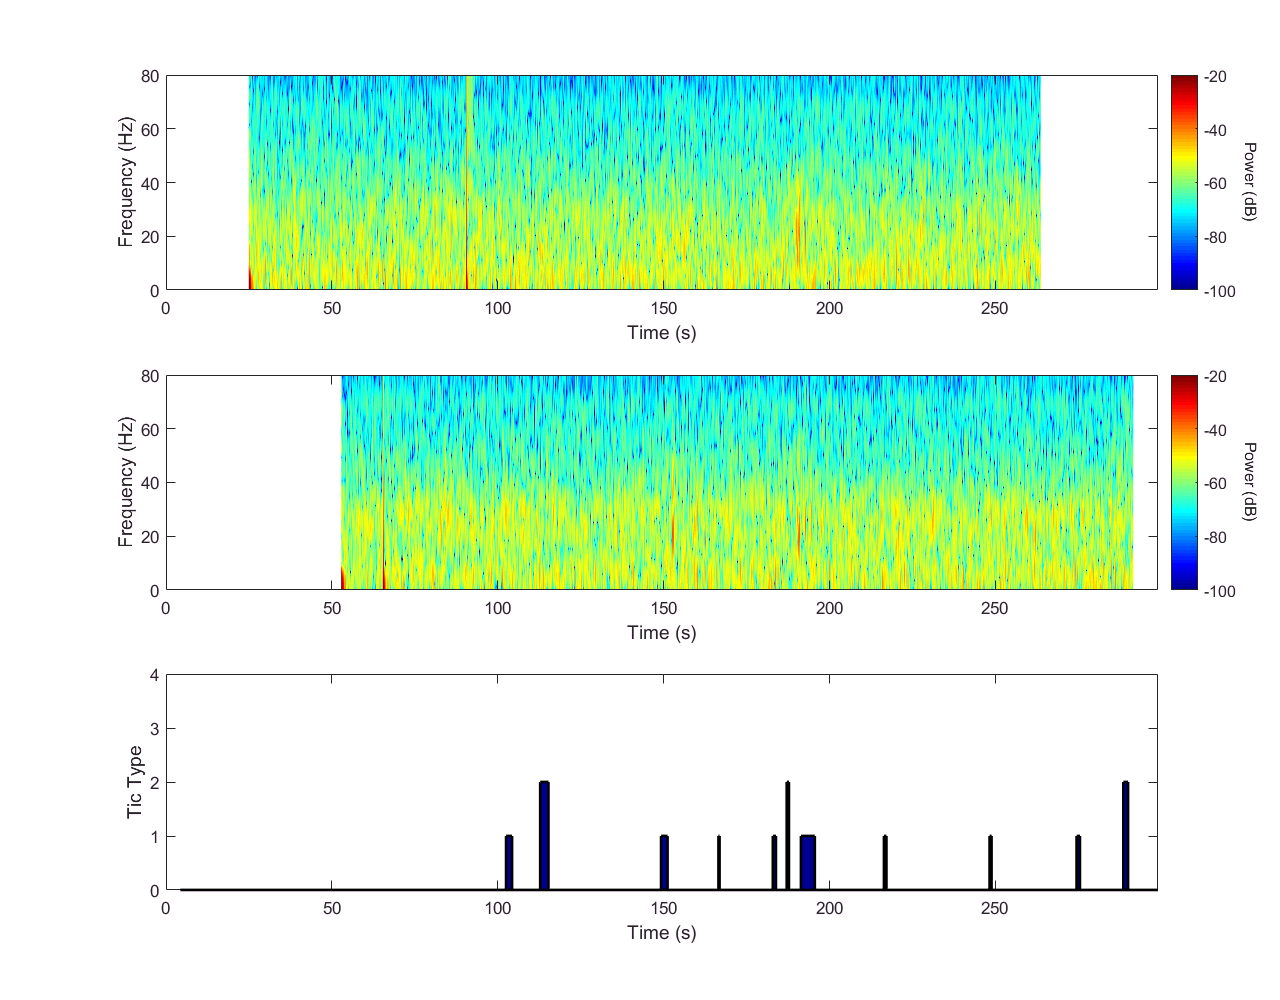

Frequency_Range = 0:0.01:80;
[~,~,Data.Left_DBS.SpectTime,Data.Left_DBS.SpectData] = spectrogram(Data.Left_DBS.data(:,3), round(Data.Left_DBS.SamplingRate*0.2), round(Data.Left_DBS.SamplingRate*0.1), Frequency_Range, Data.Left_DBS.SamplingRate);
[~,~,Data.Right_DBS.SpectTime,Data.Right_DBS.SpectData] = spectrogram(Data.Right_DBS.data(:,3), round(Data.Right_DBS.SamplingRate*0.2), round(Data.Right_DBS.SamplingRate*0.1), Frequency_Range, Data.Right_DBS.SamplingRate);

largeFigure(1801, [1280 1000]); clf; colormap jet;
subplot(3,1,1);
imagesc(Data.Left_DBS.SpectTime - Data.DBS_Bias(1), Frequency_Range, 10*log10(Data.Left_DBS.SpectData)); axis xy;
xlabel('Time (s)','fontsize',15);
ylabel('Frequency (Hz)','fontsize',15);
set(gca,'fontsize',13);
xlim([0 max(Data.Marker.time - Data.EMG_Bias)]);
caxis([-100 -20]); addColorbar('Power (dB)');

subplot(3,1,2);
imagesc(Data.Right_DBS.SpectTime - Data.DBS_Bias(2), Frequency_Range, 10*log10(Data.Right_DBS.SpectData)); axis xy;
xlabel('Time (s)','fontsize',15);
ylabel('Frequency (Hz)','fontsize',15);
set(gca,'fontsize',13);
xlim([0 max(Data.Marker.time - Data.EMG_Bias)]);
caxis([-100 -20]); addColorbar('Power (dB)');

subplot(3,1,3);
area(Data.Marker.time - Data.EMG_Bias, Data.Marker.data,'linewidth',2);
xlabel('Time (s)','fontsize',15);
ylabel('Tic Type','fontsize',15);
set(gca,'fontsize',13);
axis([0 max(Data.Marker.time - Data.EMG_Bias) 0 4]);

## Left Side ROC Curve

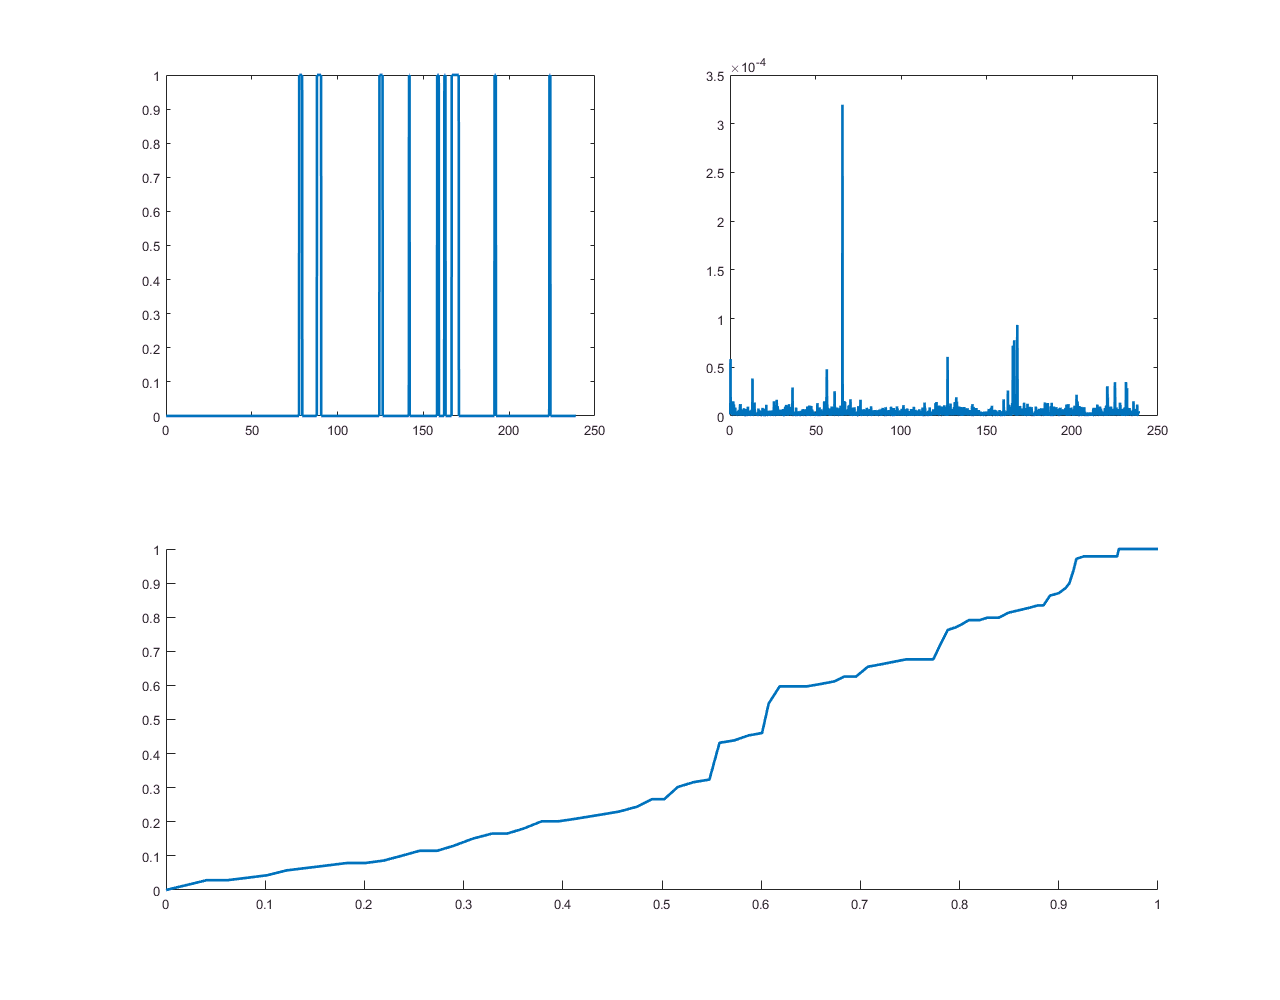

% Define Frequency of Interest
CenterFreq = 22.5;
StimDuration = 50;

% Compute Detection and ROI
Label = Data.Marker.data > 0;
Label = interp1(Data.Marker.time - Data.EMG_Bias, double(Label), Data.Left_DBS.SpectTime - Data.DBS_Bias(1));

Scores = mean(Data.Left_DBS.SpectData(Frequency_Range > CenterFreq - 2.5 & Frequency_Range < CenterFreq + 2.5, :),1);
[FalsePositive,TruePositive,Threshold] = computeROC(Label,Scores,1,'Duration',StimDuration);

largeFigure(1802,[1280 1000]); clf;
subplot(2,2,1); cla;
plot(Data.Left_DBS.SpectTime, Label, 'linewidth', 2);
subplot(2,2,2);
plot(Data.Left_DBS.SpectTime, Scores, 'linewidth', 2);
subplot(2,1,2); cla; hold on;
plot(FalsePositive, TruePositive, 'linewidth', 2);

## Right Side ROC Curve